# Human vs Machine Learning

Let's take a closer look at the difference between how we learn as humans and how machines learn.

Consider this relation between two variables, $x$ and $y$. 

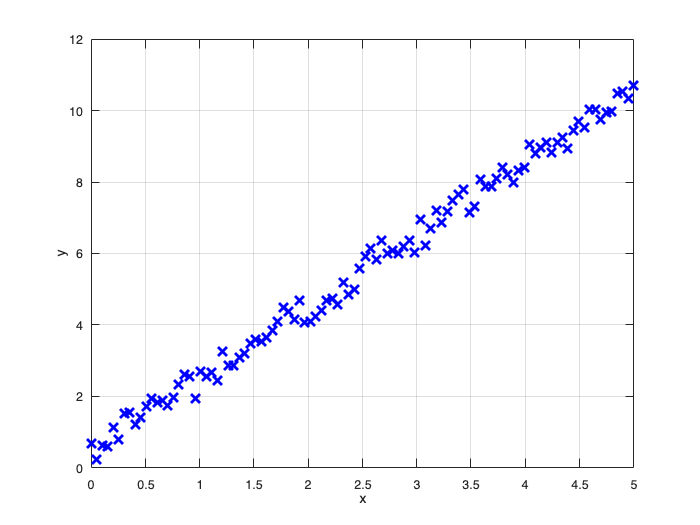

clear; clf; 
m = 2; b = 0.5;
x = linspace(0,5,100);
y = addrandomfluctuations(x,m,b,1);
plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
xlabel('x'); ylabel('y');
% axis([0 0.5 0 2])
grid on

*Figure 1.1. A data set that forms a straight line. But the computer doesn't know it's a straight line.*

## How we determine the best fit line

We know instinctively that this data forms a straight line, even though there's a little bit of randomness in the line. We know that we can plot a straight line that will represent this data. The straight line that fits this data set is given by $y=mx+b$, where $m$ is the slope and $b$ is the y-intercept. We can get the slope and the y-intercept using three methods. The first is we get a ruler and we draw a line that roughly passes through these points. We see that it intersects the y-axis at some point and we call that point our y-intercept. Then, we count the number of grid lines that represents the rise along the y-axis and the run along the x-axis to estimate the slope. The second method is we estimate the error between these data points and the expected value, represented by the equation of a line, and we minimize that error by doing some calculus. Minimizing gives us the slope and the y-intercept. We know this because these are the rules that mathematics taught us. 

Of course, the third method is to use the tools available to us in MATLAB.

p = polyfit(x,y,1)

p =     2.0177    0.4756


ylr = addrandomfluctuations(x,p(1),p(2),0.0)

ylr =     0.4756    0.5775    0.6794    0.7813    0.8832    0.9851    1.0870    1.1889    1.2908    1.3927    1.4946    1.5965    1.6984    1.8003    1.9022    2.0041    2.1060    2.2079    2.3098    2.4117    2.5136    2.6155    2.7174    2.8193    2.9212    3.0231    3.1250    3.2269    3.3288    3.4307    3.5326    3.6345    3.7364    3.8383    3.9402    4.0421    4.1440    4.2459    4.3478    4.4497    4.5516    4.6535    4.7554    4.8573    4.9592    5.0611    5.1630    5.2649    5.3668    5.4688


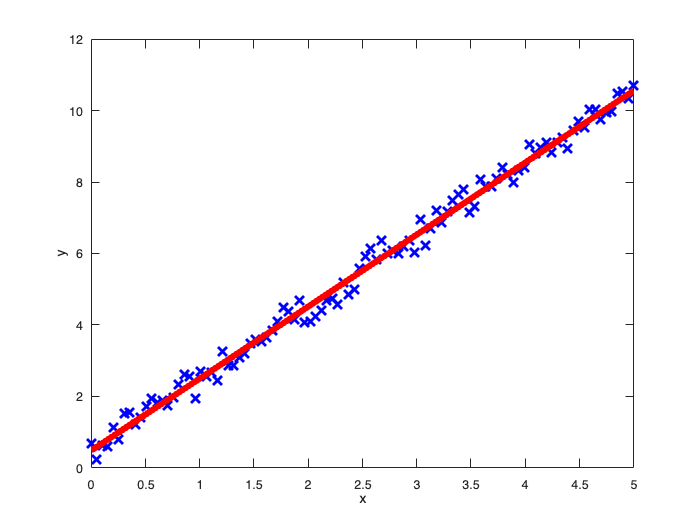


plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
hold on
plot(x,ylr, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
% axis([0 0.5 0 2])
hold off

*Figure 1.2. Predicted best fit line using the linear regression algorithm of MATLAB.*

An alternative solution is shown below using the function fitlm().

% % use linear regression to determine the best fit
% model = fitlm(x,y)
% 
% % display the computed coefficients
% model.Coefficients
% 
% % extract the slope and yintercept to the variables
% yintercept = model.Coefficients.Estimate(1,1)
% slope = model.Coefficients.Estimate(2,1)
% 
% % generate the y data set from linear regression
% ylr = model.Fitted;
% 
% plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
% hold on
% plot(x,ylr, 'r', 'LineWidth',5)
% xlabel('x'); ylabel('y');
% hold off

*Figure 1.2. Predicted best fit line using the linear regression algorithm of MATLAB.*

## How a computer determines the best fit line

A computer doesn't know any of these rules. What the computer does after it gets the data is that it'll make several guesses for the slope and the y-intercept until the error becomes really small. In each guess, it rewrites some parameters that it uses so that the error becomes smaller and smaller. When the error is small enough, then the computer returns the final value of the slope and the y-intercept to represent the line. After all of that, the computer still doesn't know what the mathematical rules are.

This short code is a machien learning model that will solve for the best fit line of the given data $x$ and $y$.

% Alternative 1

layers = [
    sequenceInputLayer(1,"MinLength",length(x))
    fullyConnectedLayer(1)
    regressionLayer
    ];
options = trainingOptions("sgdm","MaxEpochs",100,...
    "InitialLearnRate",0.0001,...
    "Plots","training-progress")

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                  CheckpointPath: ''


Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         7.50 |         28.1 |      1.0000e-04 |
|      50 |          50 |       00:00:01 |         0.51 |          0.1 |      1.0000e-04 |
|     100 |         100 |       00:00:01 |         0.25 |      3.2e-02 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


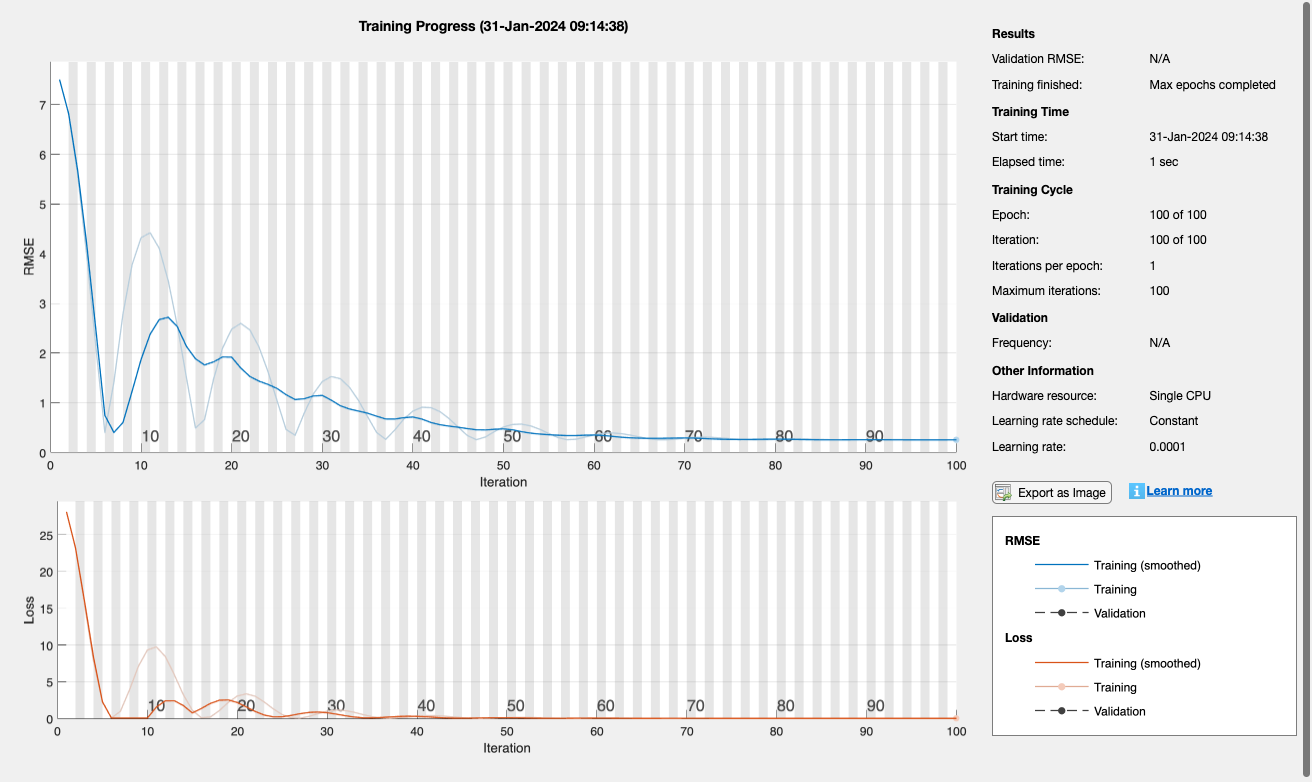

net = trainNetwork(x,y,layers,options);

*Figure 1.3. Training progress of the model.*

ymach = net.predict(x)

ymach = 1×100 single row vector
    0.4877    0.5890    0.6902    0.7914    0.8926    0.9938    1.0950    1.1962    1.2974    1.3986    1.4998    1.6010    1.7022    1.8034    1.9046    2.0058    2.1070    2.2082    2.3094    2.4106    2.5118    2.6130    2.7142    2.8154    2.9166    3.0178    3.1190    3.2202    3.3214    3.4227    3.5239    3.6251    3.7263    3.8275    3.9287    4.0299    4.1311    4.2323    4.3335    4.4347    4.5359    4.6371    4.7383    4.8395    4.9407    5.0419    5.1431    5.2443    5.3455    5.4467


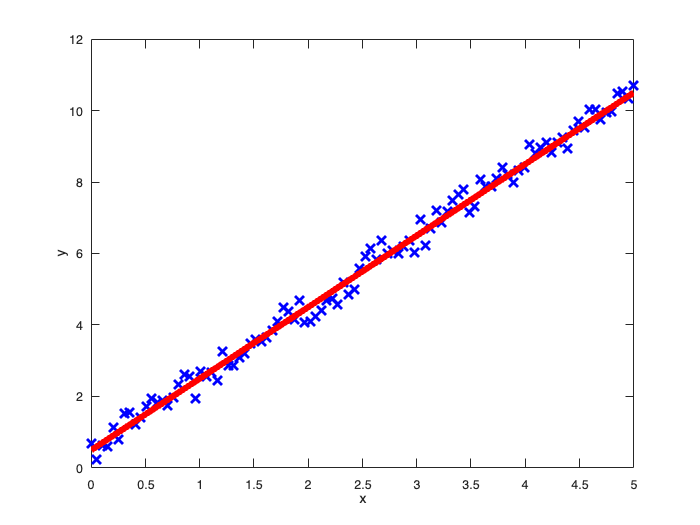

plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
hold on
plot(x,ymach, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
hold off

*Figure 1.4. Predicted best fit line by the machine learning model.*

## 1.3 Comparing human vs machine learning

As you can see from the code, it provides a numerical value for the slope and the y-intercept in the variable $p$, where the first element is the slop and the second element is the y-intercept. 

p

p =     2.0177    0.4756


We can compare that to the given $m=2$ and $b=0.5$. We can further estimate the error of $y$ for a given value of $x$ based on the data. 

xtest = 3*ones(1,length(x));
ytest = net.predict(xtest)

ytest = 1×100 single row vector
    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992    6.4992


Using $m=2$ and $b=0.5$, we find that the true value is 

ytrue = m*xtest + b

ytrue =     6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000


error = 100*abs(ytrue-ytest)/ytrue

error = single
0.0117

MSE = mean(error.^2)

MSE = single
1.3605e-04

Comparing with the actual value of 6.5, we have an error that is about 7%.

Why are we still solving for the error even if the calculations were performed by a computer? As you will soon learn, computers learn based on statistical techniques, which is why their guesses will not always be exact. To a computer, the result indicated by the red line in the graph is the most probable result from the given data.

% % Alternative 2
% net = fitnet(1,'trainscg');  %% algorithm is a scaled conjugate gradient
%                              %% with gradient descent ('traingd') and gradient descent with momentum ('traingdm')
%                              %% the fittings are non-linear
% % view(net);
% [net,tr] = train(net,x,y);
% view(net);
% ypred = net(x);             %% solves for the predicted value given the x data
% perf = perform(net,x,y);    %% solves for the mean-squared error
% 
% xtest = 3
% ytest = net(xtest)
% ytrue = m*xtest + b
% error = 100*abs(ytrue-ytest)/ytrue
% MSE = mean(error.^2)

## 1.4 Functions Used

This is the function that adds a random-sized vertical amplitude at each data point to make the data set look randomized.

function yrand = addrandomfluctuations(x,m,b,fluctuationsize)

    for i = 1:length(x)
        yrand(i) = m*x(i) + b + fluctuationsize*(rand(1)-0.5);
    end

end